#### **3. Considere um array de tamanho T que serve de base à implementação de uma memória associativa (por exemplo em Java). Assuma que a função de hash devolve um valor entre 0 e T − 1 com todos os valores igualmente prováveis.**

**(a) **Determine por simulação a probabilidade de haver pelo menos uma colisão (pelo menos 2 keys mapeadas pela função de hash para a mesma posiçao do array) se forem introduzidas 10 keys num array de tamanho T = 1000.

experiencias_a = randi(1000, 10, 1e6);

casosFavoraveis = 0;

for k=1:1e6
    if length(unique(experiencias_a(:,k))) == 10
        casosFavoraveis = casosFavoraveis + 1;
    end
end

probSimulacao_a = casosFavoraveis/1e6

probSimulacao_a = 0.9559

**(b)** Faça um gráfico da probabilidade da alínea (a) (estimada por simulação) em função do número de keys para todos os valores relevantes num array de tamanho T = 1000.

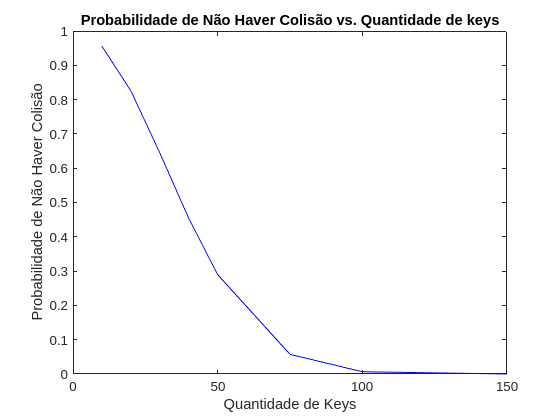

keys = [10, 20, 30, 40, 50, 75, 100, 150];
y = zeros(size(keys));

for k = 1:length(keys) 
    
    experiencias_b = randi(1000, keys(k), 1e5);

    casosFavoraveis_b = 0;
    
    for i=1:1e5
        if length(unique(experiencias_b(:,i))) == keys(k)
            casosFavoraveis_b = casosFavoraveis_b + 1;
        end
    end
    
    y(k) = casosFavoraveis_b/1e5;
end

plot(keys, y, 'b')
xlabel('Quantidade de Keys')
ylabel('Probabilidade de Não Haver Colisão')
title('Probabilidade de Não Haver Colisão vs. Quantidade de keys')

**(c)** Para um número de keys igual a 50, represente graficamente a variação da probabilidade (estimada por simulação) de não haver nenhuma colisão em função do tamanho T do array (assuma os tamanhos T de 100 até 1000 com incrementos de 100).

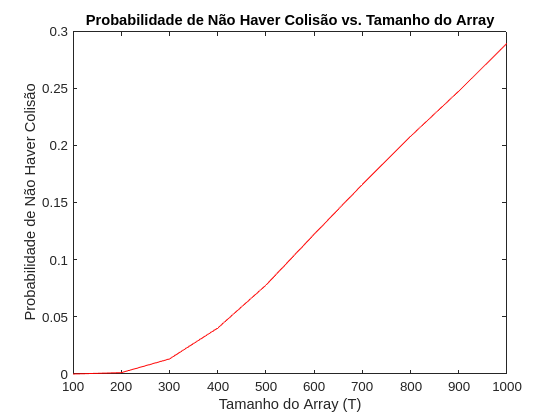

keys = 50;
T = 100:100:1000;
y = zeros(size(T));

for k = 1:length(T)
    experiencias_c = randi(T(k), keys, 1e5);
    
    casosFavoraveis_c = 0;

    for i = 1:1e5
        if length(unique(experiencias_c(:,i))) == keys
            casosFavoraveis_c = casosFavoraveis_c + 1;
        end
    end

    y(k) = casosFavoraveis_c / 1e5;
end

plot(T, y, 'r')
xlabel('Tamanho do Array (T)')
ylabel('Probabilidade de Não Haver Colisão')
title('Probabilidade de Não Haver Colisão vs. Tamanho do Array')